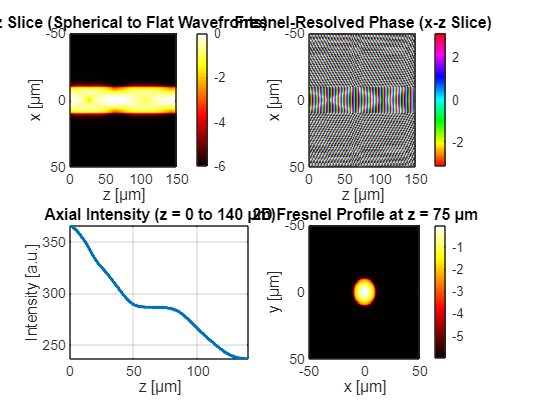

%% Parameters
lambda = 4e-6;          % Wavelength [m] (4 μm)
ri = 10e-6;             % Inner radius [m] (10 μm)
ro = 4 * ri;            % Outer radius [m] (40 μm)
Nx = 128; Ny = 128; Nz = 1024; % 3D grid dimensions
Nx2D = 256; Ny2D = 256; % 2D input grid dimensions
gridExtent = 10 * ri;   % Transverse grid extent [m] (±100 μm)
zMax = 15 * ri;         % Propagation distance [m] (150 μm)
n_cladding = 1.45;      % Cladding refractive index
alpha = 0.6;            % Optimal α (w0 = α*ri)
dz = zMax/Nz;
% Grid coordinates
x = linspace(-gridExtent/2, gridExtent/2, Nx);
y = linspace(-gridExtent/2, gridExtent/2, Ny);
z = linspace(0, zMax, Nz);
x2D = linspace(-gridExtent/2, gridExtent/2, Nx2D);
y2D = linspace(-gridExtent/2, gridExtent/2, Ny2D);

%% Create waveguide index profile (3D)
[X3, Y3, Z3] = meshgrid(x, y, z);
R = sqrt(X3.^2 + Y3.^2);
n = ones(size(R)) * n_cladding; % Cladding (n=1.45)
n(R <= ri) = 1;                 % Core (n=1, vacuum)

%% Input Gaussian beam (optimized)
w0 = alpha * ri;         % Beam waist
k = 2*pi/lambda;         % Wavenumber
zR = (pi * w0^2)/lambda; % Rayleigh range
[X2D, Y2D] = meshgrid(x2D, y2D);
E_input = exp(-(X2D.^2 + Y2D.^2)/w0^2) .* exp(1i*k*(X2D.^2 + Y2D.^2)/(2*zR));

%% Preallocate field storage
E_all_z = zeros(Nx2D, Ny2D, Nz);
E_all_z(:, :, 1) = E_input;

%% Spatial frequency grids (critical for angular spectrum)
dx = x2D(2) - x2D(1);
dy = y2D(2) - y2D(1);
fx = (-Nx2D/2:Nx2D/2-1)/(Nx2D*dx);
fy = (-Ny2D/2:Ny2D/2-1)/(Ny2D*dy);
[Fx, Fy] = meshgrid(fx, fy);

%% Split-step Fourier propagation (revised)  %Deep Seek was used to help write 
for iz = 2:Nz
    % Step 1: Apply absorption (reduced cladding loss)
    absorption = ones(Nx2D, Ny2D);
    absorption(sqrt(X2D.^2 + Y2D.^2) > ri) = exp(-1e2 * k * dz); % Reduced loss
    E = E_all_z(:, :, iz-1) .* absorption;
    
    % Step 2: Propagate using angular spectrum
    E_fft = fftshift(fft2(E));
    H = exp(1i * k * dz * sqrt(1 - (lambda*Fx).^2 - (lambda*Fy).^2));
    E = ifft2(ifftshift(E_fft .* H));
    
    % Store field
    E_all_z(:, :, iz) = E;
end

%% Visualization (Four Plots)
figure;

% ----------------------------------------
% Plot 1: x-z Slice (Log Scale for Visibility)
% ----------------------------------------
subplot(2, 2, 1);
xZ_slice = squeeze(abs(E_all_z(Ny2D/2, :, :)).^2);
imagesc(z*1e6, x2D*1e6, log10(xZ_slice + 1e-6));
title('x-z Slice (Spherical to Flat Wavefronts)');
xlabel('z [μm]'); ylabel('x [μm]');
colormap(gca, 'hot'); 
colorbar;
clim([-6 0]); % Adjusted color limits

% ----------------------------------------
% Plot 2: Fresnel-Resolved Beam (x-z Phase)
% ----------------------------------------
subplot(2, 2, 2);
fresnel_slice = squeeze(angle(E_all_z(Ny2D/2, :, :)));
imagesc(z*1e6, x2D*1e6, fresnel_slice);
title('Fresnel-Resolved Phase (x-z Slice)');
xlabel('z [μm]'); ylabel('x [μm]');
colormap(gca, 'hsv'); 
colorbar;

% ----------------------------------------
% Plot 3: Axial Intensity (z = 0 to 140 μm)
% ----------------------------------------
subplot(2, 2, 3);
mask_core = (sqrt(X2D.^2 + Y2D.^2) <= ri);
energy_core = squeeze(sum(sum(abs(E_all_z).^2 .* mask_core, 1), 2));
plot(z*1e6, energy_core, 'LineWidth', 2);
title('Axial Intensity (z = 0 to 140 μm)');
xlabel('z [μm]'); ylabel('Intensity [a.u.]');
xlim([0 140]); 
grid on;

% ----------------------------------------
% Plot 4: 2D Fresnel Profile at z = 75 μm)
% ----------------------------------------
subplot(2, 2, 4);
[~, z75_idx] = min(abs(z - 75e-6)); % Index for z = 75 μm
profile_2D = abs(E_all_z(:, :, z75_idx)).^2;
imagesc(x2D*1e6, y2D*1e6, log10(profile_2D + 1e-6));
title('2D Fresnel Profile at z = 75 μm');
xlabel('x [μm]'); ylabel('y [μm]');
colormap(gca, 'hot'); 
colorbar;